# **数据集准备**

% 数据集准备
clear; clc; close  % 清空工作区，关闭所有图形窗口，清空命令行

% 训练集实际值（ResTrain）和预测值（preTrain）
n_train = 500;
% 生成训练集的实际值：采用正态分布生成，均值200，标准差50
ResTrain = randn(n_train, 1) * 50 + 200;
% 生成训练集的预测值：在实际值的基础上加上一些噪声
preTrain = ResTrain + randn(n_train, 1) * 20+20;

% 测试集实际值（ResTest）和预测值（preTest）
n_test = n_train * 0.3;
% 生成测试集的实际值：与训练集类似，采用正态分布，均值200，标准差50
ResTest = randn(n_test, 1) * 50 + 200;
% 生成测试集的预测值：在实际值的基础上加上一些噪声
preTest = ResTest + randn(n_test, 1) * 25 + 20;

**使用前应当准备好数据集（包括预测值和实际值）**

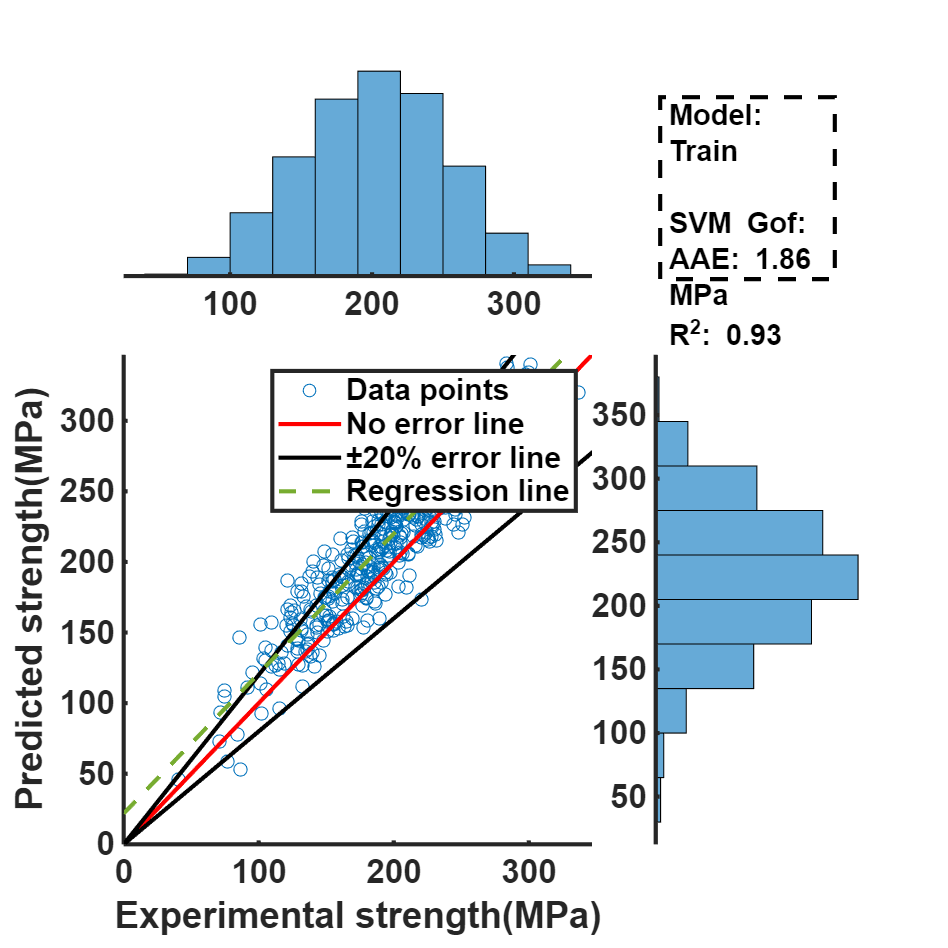

% 绘图
GofIndex=[1.86,0.93];  % 训练集评价指标
% Res: 真实值；Pre：预测值；GofIndex：评价指标；Cate：训练集名称。
plotRes2Pre(ResTrain, preTrain, GofIndex, 'Train');  % 绘制训练集的图形

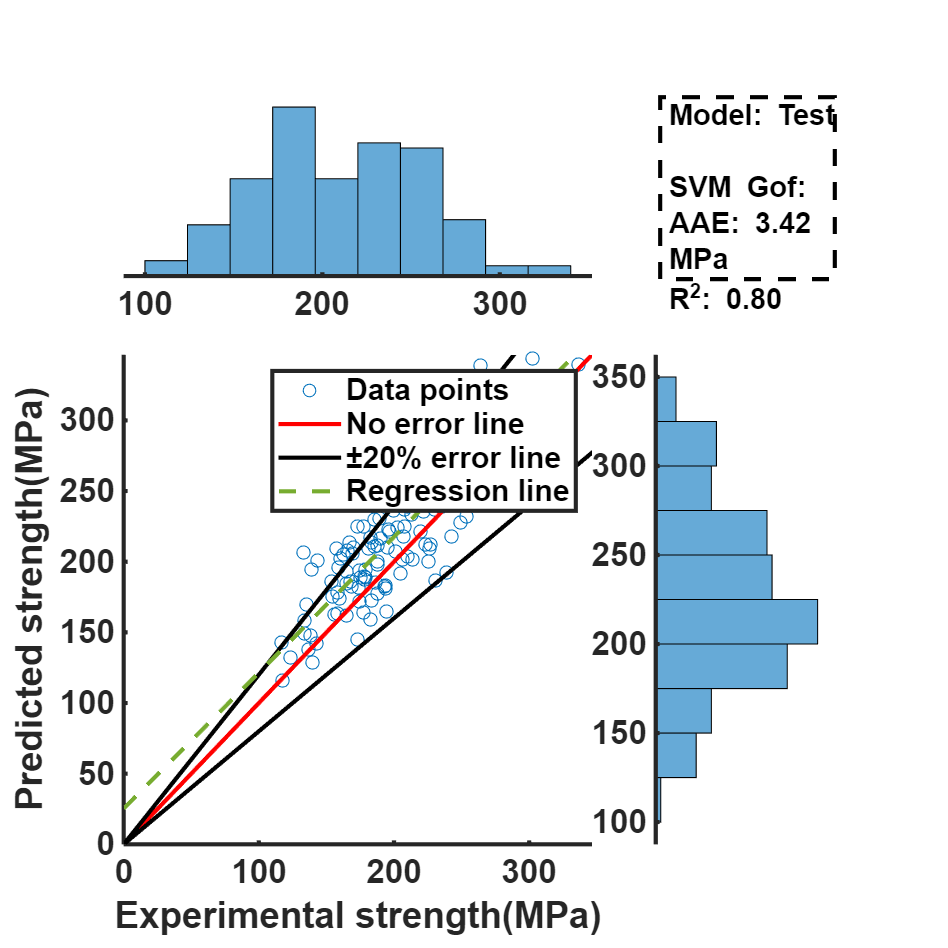


GofIndex=[3.42,0.80];  % 测试集评价指标
plotRes2Pre(ResTest, preTest, GofIndex, 'Test');  % 绘制测试集的图形

# Function

% 绘制散点图与回归线的函数
function plotRes2Pre(Res, Pre, GofIndex, Cate)
%  输入:
%      Res: 真实值；Pre：预测值；GofIndex：评价指标；Cate：训练集/测试集名称。


figure('Position', [0, 0, 900, 900]); % 创建一个900x900像素的图形窗口

% 设置y轴的最大值，并为误差线设定上下界限
y = max(Res)*1.1;
yu = y * 1.2;  % 上界限
yl = y * 0.8;  % 下界限

% 绘制散点图
subplot(3, 3, [4 5 7 8]);  % 将散点图放置在图形的中间位置
hold on;
scatter(Res, Pre, 40, [168, 207, 232] ./ 255, "o", "MarkerEdgeColor", [0, 113, 188]./255);  % 绘制散点，设置颜色

% 绘制误差线：真实值与预测值的对角线以及20%的误差线
plot([0, y], [0, y], 'LineWidth', 2, 'Color', 'r');  % 回归线（红色）
plot([0, y], [0, yu], 'LineWidth', 2, 'Color', [0, 0, 0]);  % ±20%误差上界（黑色）
plot([0, y], [0, yl], 'LineWidth', 2, 'Color', [0, 0, 0]);  % ±20%误差下界（黑色）

% 绘图修饰
xlim([0, max(Res) + 10]);  % 设置x轴范围
ylim([0, max(Res) + 10]);  % 设置y轴范围
ylabel('Predicted strength(MPa)');  % 设置y轴标签
xlabel('Experimental strength(MPa)');  % 设置x轴标签

% 设置图例
LGD = {'Data points', 'No error line', '±20% error line'};  % 图例内容
legend(LGD);  % 显示图例

% 创建文本框，显示模型和性能指标
textString = sprintf('Model: %s\n\n%s Gof:\nAAE: %.2f MPa\nR^{2}: %.2f', ...
    Cate, 'SVM', GofIndex(1), GofIndex(2));  % 使用sprintf格式化字符串
annotation('textbox', ...
    [0.696428571428569 0.705580861367508 0.184151785714286 0.191913443871675], ...
    'String', textString, ...
    'Margin', 3, ...
    'LineWidth', 2, ...
    'LineStyle', '--', ...
    'FontWeight', 'bold', ...
    'FontSize', 14, ...
    'FitBoxToText', 'off');  % 设置文本框的位置、样式和内容

% 设置坐标轴参数
set(gca, 'FontSize', 16, 'FontWeight', 'bold', 'GridLineStyle', '--', 'LineWidth', 2);

% 绘制回归线
p_Res = polyfit(Res, Pre, 1);  % 计算回归线的系数
x = [0, max(Res) * 1.1];  % 设置回归线的x轴范围
plot(x, polyval(p_Res, x), 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Regression line');  % 绘制回归线

% 绘制上方的直方图
plotHis([1 2], Res);

% 绘制右侧的直方图（顺时针旋转90度）
plotHis([6 9], Pre);
view([90 -90]);  % 顺时针旋转90度

hold off;  % 结束绘图
end

% 绘制直方图的函数
function plotHis(position, data)
%  输入:
%      position：直方图位于子图中的位置；data：直方图对应的数据。


subplot(3, 3, position);  % 将直方图放置在指定位置
histogram(data, 'NumBins', 10);  % 绘制直方图，设置无边框
box("off");  % 去除图形框

% 去除不需要的元素，保持横坐标
ax2 = gca;  % 获取当前坐标轴
ax2.YColor = 'none';  % 不显示纵坐标线
ax2.YTickLabel = {};  % 去掉纵坐标的刻度标签

% 设置坐标轴参数
set(gca, 'FontSize', 16, 'FontWeight', 'bold', 'GridLineStyle', '--', 'LineWidth', 2);
end